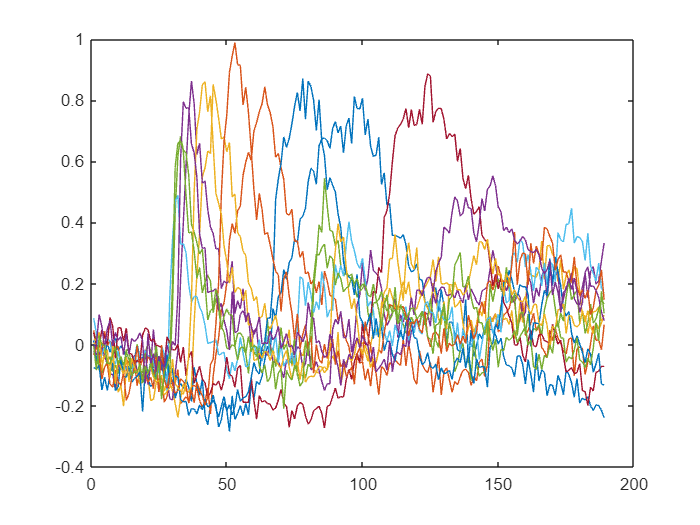

figure;
plot(info.analysis{1}.respMatPlot);

% Pull out Trial-averaged but not ROI-averaged responses (from Fly #1)
p6 = info.analysis{1,1}.indFly{1,4}.p6_averagedTrials.snipMat;
% permute dimensions so that the dimension of epochs are the third
% dimension
p6 = permute(p6,[3,2,1]);
% Convert a cell array to a matrix so that it's easier to plot
% p6mat should be a 3D matrix with time x ROI x epoch dimensions
p6mat = cell2mat(p6);
% for example, visualize the dF/F responses of all ROIs to epoch #1
m = ones(1,10);
m = m*60;
m(2:2:10) = m(2:2:10) *-1;
o = 1:10;

o(1:2:7) = -120:30:-30;
o(2:2:8) = 120:-30:30;
o(9) = -135;
o(10) = 135;

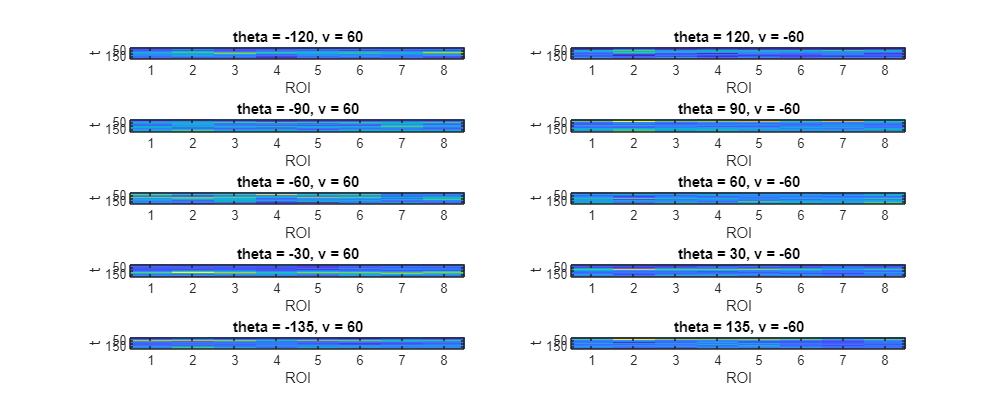


figure('units','normalized','outerposition',[0 0 1 1]);
for n = 1:10
    subplot(5,2,n)   
    imagesc(p6mat(:,:,n));
    title(sprintf('theta = %d, v = %d', o(n),m(n)))
    xlabel('ROI')
    ylabel('t')
    % sgtitle(sprintf('DataPath{%d}'))
end

% saveas(gcf,sprintf('BarsAburpt001_00%d.png', dP))